# MANIPULATOR ROBOTICS : SHORT PROJECT

Authors : [G11-A]

- Daniel Santiago Corona

- Iván López Rodríguez

URL : [https://drive.matlab.com/sharing/0993a810-f342-4e41-94ec-27e549534823](https://drive.matlab.com/sharing/0993a810-f342-4e41-94ec-27e549534823)

Durante la realización de esta práctica hemos encontrado incidencias técnicas de Matlab con:

- El uso de la figura necesaria para el apartado del second approach, que no se reseteaba tras cada Section Break ,tal y como comentamos al llegar a ese apartado lo solventamos no usando Section Breaks durante la duración de todo ese apartado, perdiendo en modularidad. Además, esta 'figure' al ser abierta a través de un 'open' genera una ventana de pop-up que genera problemas si se cierra antes de terminar los procesos que ocurren en ella.

- La función 'fps' y 'delay' del plot de la Robotics ToolBox para la generación de los vídeos no han funcionado correctamente, de manera que ha sido necesaria un ajuste manual de los vídeos para ajustarse al ritmo esperado de los procesos de la cirujía.

Hemos intentado ser claros y concisos en todos los apartados, pero si tiene alguna duda sobre alguno de los algoritmos que hemos diseñado por favor póngase en contacto con nosotros.

----------------------------------------

## The Robotic environment (10%)

### Operating table.

 It can be raised, lowered, and tilted in any direction, and an auxiliary table for the tools. 

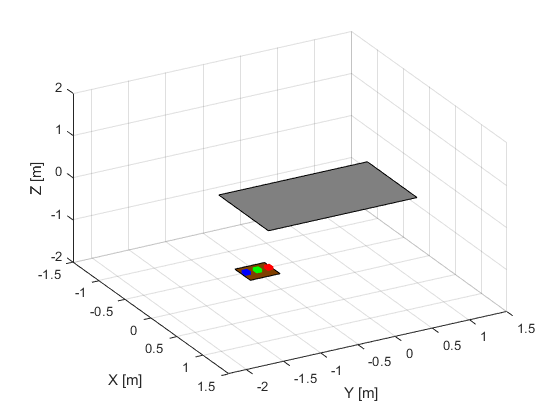

clear , clf

f1 = figure;

X = [-2.5 -2.5 2.5 2.5];
Y = [-1.2 1.2 1.2 -1.2];
Z = [0 0 0 0];

Xt = [0.55 0.55 0.85 0.85];
Yt = [-1.5 -1.1 -1.1 -1.5];
Zt = [-0.65 -0.65 -0.65 -0.65];

% Scaling
table = 0.4*[X ;Y ;Z];
tool_table = 1*[Xt; Yt; Zt];

% Homogeneous Coordinates
table = [table ;ones(1,length(table))];
tool_table = [tool_table; ones(1,length(tool_table))];

% Table's rotation/translation
trans_table = trotz(-pi/2);
trans_table = trotx(-0*pi/16) * trans_table;

trans_tool_table = transl(0.7,-1.3,-0.65);

table = trans_table * table;

patch(table(1,:),table(2,:), table(3,:),[0.5 0.5 0.5])
hold on
patch(tool_table(1,:),tool_table(2,:),tool_table(3,:),[0.5 0.25 0])

%Tools
v= [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1];
v = [0.075* (v - 0.5*ones(8,3)) , ones(8,1) ];
f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];

%Tool 1
v1 = (trans_tool_table * v')';
v1 = (transl(0,0.15,0.075/2) * v1')';
v1 = v1(:,1:3);
FVsPlot(f,v1,[1,0,0],0,1)

%Tool 2
v2 = (trans_tool_table * v')';
v2 = (transl(0,0,0.075/2) * v2')';
v2 = v2(:,1:3);
FVsPlot(f,v2,[0,1,0],0,1)

%Tool 3
v3 = (trans_tool_table * v')';
v3 = (transl(0,-0.15,0.075/2) * v3')';
v3 = v3(:,1:3);
FVsPlot(f,v3,[0,0,1],0,1)

% Camera parameters
view(3)

xlim([-1.50 1.50])
ylim([-2.25 1.50])
zlim([-2.00 2.00])

view([60.89 37.18])

### 3D model of the human body 

The scale has been calculated to have a human measuring around 1,8 meters.

It is worth noticing that the rotation/translation matrix of the operating table is being used here, in hte composition of the matrix of the human body. Since it need to be lying on the table, it depends on the table's position. This is also noticeable in further elements dependent on the human body (and therefore dependent on the table).

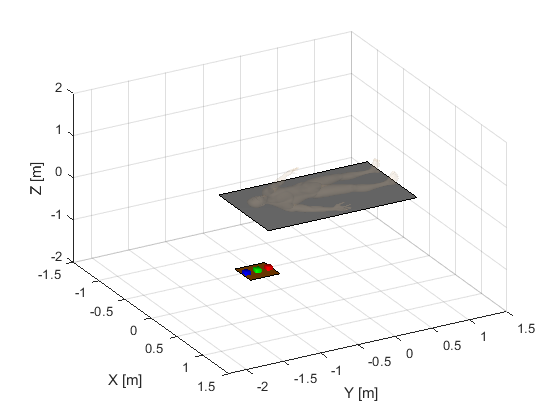

body = load("F_V_Human_Body.mat");

% Body Scaling and Homogeneous Coordinates
SH = [0.09 * body.V , ones([24461,1]) ];

% Traslation to the center of our Universe
bodyCenter = ( max(SH) + min(SH) ) ./2;
bodyCenter = bodyCenter(1:3);

trans_body = transl(0,0,0.2)*trans_table*trotz(-pi/2);

VBody = (trans_body * transl(-bodyCenter) * (SH)')';

% Back to Cartesian coordinates
VBody = VBody(:,1:3);

FVsPlot(body.F,VBody,[229/255,194/255,152/255],1,0.1)

### Human skull model

It (obviously) has to be embedded in the head of the human. Its movement matrix is composed using the human body's movement matrix and further elementary movement matrices.

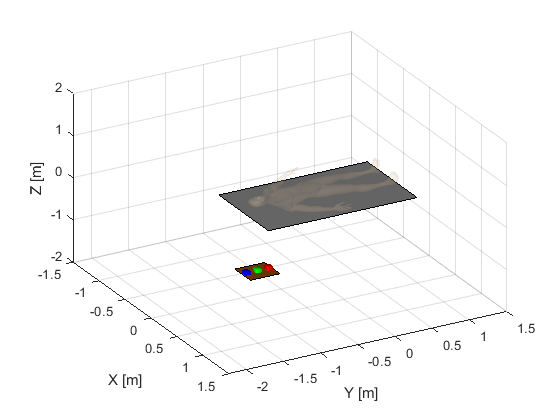

skull = load("F_V_N_Skull.mat");

% Body Scaling and Homogeneous Coordinates

% TRY SWAPPING THESE TWO SCALINGS TO CHECK THAT THE SKULL IS ACTUALLY THERE
%SH = [0.0125 * skull.Ve , ones(length(skull.Ve),1) ];
SH = [0.0065 * skull.Ve , ones(length(skull.Ve),1) ];

% Traslation to the center of our Universe
skullCenter = ( max(SH) + min(SH) ) ./2;
skullCenter = skullCenter(1:3);

trans_skull = transl(0,0,0)*trans_body*transl(0,1.65/2,0)*trotx(-pi/2);

SH = (trans_skull * transl(-skullCenter) * SH')';

VSkull = SH(:,1:3);

FVsPlot(skull.Fa,VSkull,0.9*[227/255,218/255,201/255],0,0.1)

### Box surrounding the head

Having scaled the human body to have a head that fits perfectly in a 0.25 (meters) sided box, now we just need to center the box to the human's head. 

**Notice we have modified the box for it not to be squared**, this is important since we noticed that the set of Dicom images does not form a square space of 0.25*0.25*0.25 meters, the Z component of the space is shorter that the X and Y ones since there are 112 images taken at a 1.4 milimeters distance which amounts to 0.1568 meters. 

**Also the box does not fit all the way to the top of the head since ****Dicom images do not represent the top of the skull****. This way our black box is a true representation of the space generated by the Dicom images.**

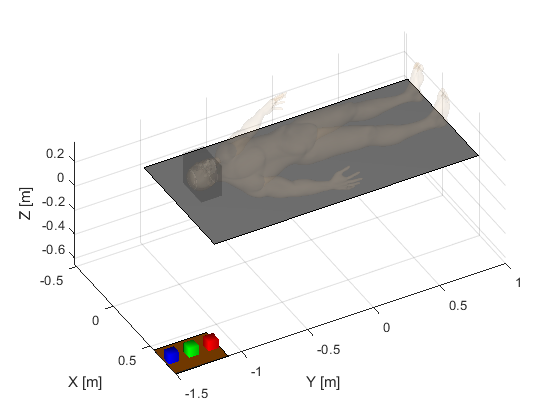

v= [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1];
v = [0.25* (v - 0.5*ones(8,3)) , ones(8,1) ];

v(:,3) = (v(:,3) .* 0.1568) ./ 0.25;

v = (trans_skull * v')';

f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];

v = v(:,1:3);

FVsPlot(f,v,[0,0,0],0,0.1)
axis equal

### About the Dicom / Image reference frame

The image (or Dicom) reference frame and its relation to the Universe reference frame is essential to place the fiducials in our enviroment.

Since we have used (and reused) the movement matrices for each element of the enviroment, we have been able to generate each successive dependent element matrix by composing with the matrix of a previous element. This method is also used here to help us generate the M_U_B matrix, that is the matrix such that :

    P_U = M_U_B * P_B

where U corresponds to the Universe reference frame and B corresponds to the Box reference frame. We chose the name 'Box reference frame', but understand this is a generalization of the "Image reference frame" since an image would be 2D and the Box reference frame is to be used for the spacial region formed by the successive Dicom images.

First we calculated the would-be M_U_B if there were no movement/rotations applied to the box, we calculated this matrix by-hand, then we transform this matrix to the actual M_U_B by composing it with the skull matrix , which has the body and table matrices composed in it .


% Original box's M_U_B
M_U_B = [[1 0 0 0] ; [0 1 0 0] ; [0 0 1 0] ; [-0.125 -0.125 -0.0784 1]]'

M_U_B =     1.0000         0         0   -0.1250
         0    1.0000         0   -0.1250
         0         0    1.0000   -0.0784
         0         0         0    1.0000



% Composing the previos M_U_B to the actual position and pose of the box
M_U_B = trans_skull * troty(pi) * M_U_B;

% Testing the transformation for a box point --> universe point
M_U_B * [0 0 0 1]'

ans =    -0.1250
   -0.9034
    0.3250
    1.0000


###  Fiducials

In order to display the fiducials,we had to observe their positions in the Dicom reference frame with the given images. As we were told, we are going to show the fiducials with spheres of 0.005 meters of radius.

First of all we had to compute the coordinates of the fiducials in the Universal reference frame, after this we can display the fiducials in their correct position.

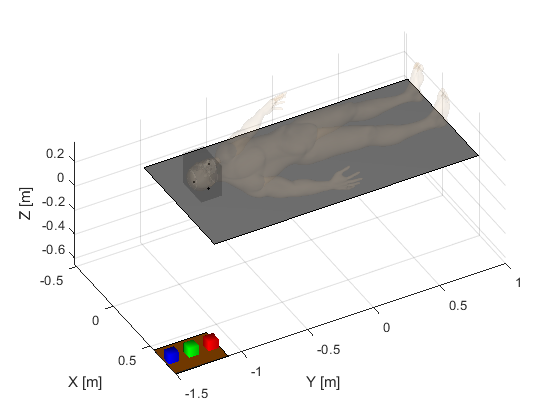

[X,Y,Z] = sphere;
r = 0.005;
%r = 0.1;

X2 = X * r;
Y2 = Y * r;
Z2 = Z * r;

fiducial94_I = [0.12163 , 0.06231 , 94*1.4/1000 1]';
fiducial94_U = M_U_B * fiducial94_I;
hold on
surf(X2+fiducial94_U(1,1),Y2+fiducial94_U(2,1),Z2+fiducial94_U(3,1),'FaceColor',[1 0 0])

fiducial65_I = [0.18563 , 0.20934 , 65*1.4/1000 1]';
fiducial65_U = M_U_B * fiducial65_I;
surf(X2+fiducial65_U(1,1),Y2+fiducial65_U(2,1),Z2+fiducial65_U(3,1),'FaceColor',[0 1 0])

fiducial32_I = [0.07109 , 0.21394 , 32*1.4/1000 1]';
fiducial32_U = M_U_B * fiducial32_I;
surf(X2+fiducial32_U(1,1),Y2+fiducial32_U(2,1),Z2+fiducial32_U(3,1),'FaceColor',[0 0 1])

### Tumor points

As we did before with the fiducials, to get the perimeter of the tumor, we have to notice which image shows the tumor in its biggest form, because these points will be considered as the center of the tumor. With some easy estimations we can compute the radius of the tumor. Finally we have to convert these points in the Universal reference frame in order to display the sphere that defines the perimeter of the tumor correctly.

xmax_I = 0.148;
xmin_I = 0.118;
ymin_I = 0.080;
ymax_I = 0.115;
zmin_I = 65*1.4/1000;
zmax_I = 89*1.4/1000;

r = max([(xmax_I-xmin_I),(ymax_I-ymin_I),(zmax_I-zmin_I)]) / 2

r = 0.0175

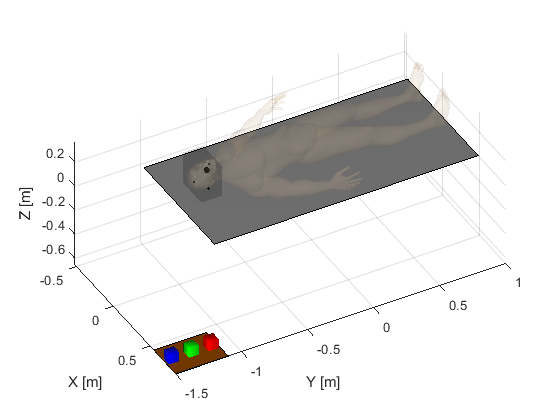

X2 = X * r;
Y2 = Y * r;
Z2 = Z * r;

tumor_center_I = [(xmax_I+xmin_I)/2, (ymax_I+ymin_I)/2, (zmax_I+zmin_I)/2, 1]';
tumor_center_U = M_U_B * tumor_center_I;

hold on
surf(X2+tumor_center_U(1,1), Y2+tumor_center_U(2,1), Z2+tumor_center_U(3,1), 'FaceColor', [1,0,0])

## *First approach (10%)  *

*Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

### Robot manipulator

Consider  the best position of manipulator to be nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

Use: p560.base & p560.tool to locate the Puma and add the tool.

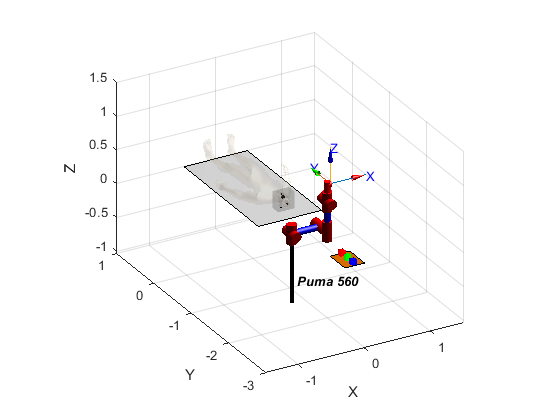

mdl_puma560
p560.base = transl(-0.2,-1.4,0);

p560.tool = transl(0.05,0,0.25);

p560.plot(qz)

xlim([-1.50 1.50])
ylim([-3 1.00])
zlim([-1.03 1.5])
view([-29.31 26.86])

### Reference Frames

Display all necessary reference frames. Use the best scale to see it.

- {LAB} Laboratory [0 0 0]

- {R} Robot

- {B} Box/Image

- {Tb} Table_body

- {Tt} Table tool

- {EE} End Efector (Not plotted explicitly , since the robot shows it anyway)

To help visualize the reference frame even more we will plot both Laboratory and Box reference frames in the following plot

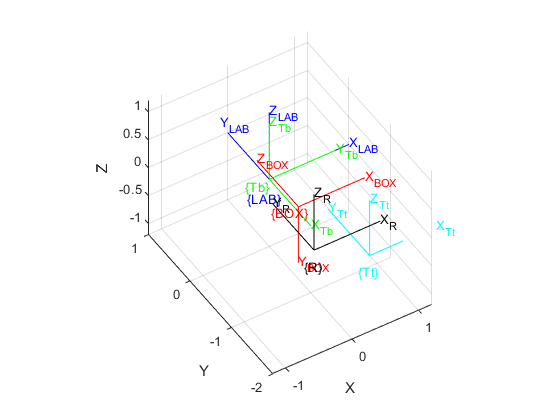

f2 = figure;
factor = 1.2;
trplot([factor*[1 0 0 0] ; factor*[0 1 0 0] ; factor*[0 0 1 0] ; [0 0 0 1]]','frame', 'LAB', 'color', 'b')
hold on
trplot(M_U_B,'frame','BOX','color','r')
trplot(trans_table, 'frame','Tb','color','g')
trplot(trans_tool_table,'frame','Tt','color','c')
trplot(p560.base,'frame','R','color','k')

ylim([-2 1.00])
view([-32.02 44.50])


clf(f2)

### Transformations

Calculate the useful reference frame transformations. We don't need many of them since all the relevant points are either declared in the Box or Universal/Laboratory reference frames.

figure(f1)
% M_A_B means the transformation such that P_A = M_A_B * P_B

M_U_Tt = trans_tool_table;
M_U_B;

% M_U_EE will not be used as the ikine function takes its arguments in the
% LAB reference frame

### Tumor points in the Robot or End Effector Frame

As we have commented in the previous block, our approach to the End Effector frame has been not to treat it directly, since the ikine functions require the points/matrices given to it to be in the Universal frame we would rather get the points we want to reach in this Universal frame AND apply the corresponding pose to it.

For instance, let's plot the robot's end effector / surgery tool being inside and outside the skull in its correct pose (being the Z axis the useful end of the tool). For demonstration purposes we will plot the tool at a 45 degrees angles when inside the head.

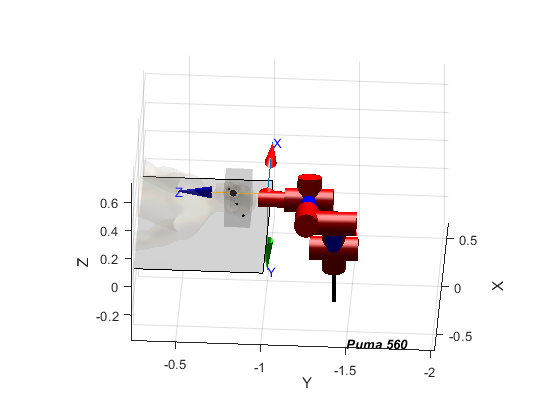

P = tumor_center_U(1:3);
Pout = transl(P) * trotx(-0.5*pi) * transl(0,0,-0.2);
Pin = transl(P) * trotx(-0.5*pi) * trotx(-pi/4);

ikiOut = p560.ikine6s(Pout);
ikiIn = p560.ikine6s(Pin);

% Before inserting the tool inside the skull
p560.plot(ikiOut)

xlim([-0.67 0.67])
ylim([-2.02 -0.24])
zlim([-0.38 0.74])
view([-86.52 34.35])

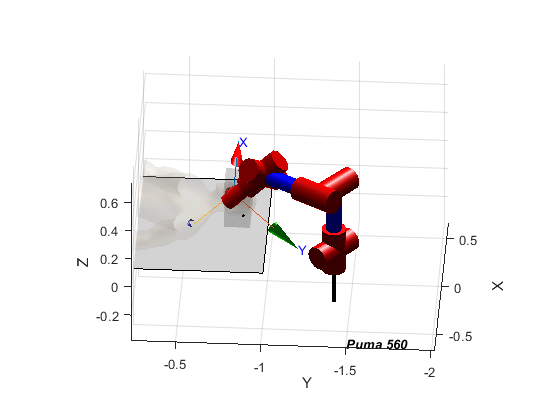

% After inserting the tool inside the skull at 45 degrees
p560.plot(ikiIn)

## Surgery (40%)

### Biopsy

#### Part 1 : Getting the biopsy needle

xlim([-0.73 1.40])
ylim([-2.64 0.18])
zlim([-0.69 0.8])
view([69.73 36.93])

tool1 = [0.8 -1.15 -0.62]

tool1 =     0.8000   -1.1500   -0.6200


tool1 = transl(tool1) * troty(pi/2) * transl(0,0,-0.25)

tool1 =          0         0    1.0000    0.5500
         0    1.0000         0   -1.1500
   -1.0000         0         0   -0.6200
         0         0         0    1.0000



ini_point = transl(p560.fkine(qz).t);
end_point = tool1;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryB11 = p560.ikine6s(real(Q),'run');

ini_point = tool1;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryB12 = p560.ikine6s(real(Q),'run');

P = tumor_center_U(1:3);
P = transl(P) * trotx(-0.5*pi) * transl(0,0,-0.25)

P =     1.0000         0         0    0.0080
         0         0    1.0000   -1.0456
         0   -1.0000         0    0.2275
         0         0         0    1.0000


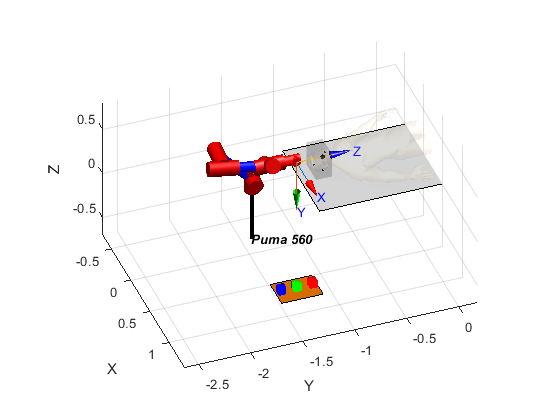


ini_point = transl(p560.fkine(qz).t);
end_point = P;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryB13 = p560.ikine6s(real(Q),'run');

trajectoryB1 = [trajectoryB11 ; trajectoryB12 ; trajectoryB13];

p560.plot(real(trajectoryB1))

%p560.plot(real(trajectoryB1),'movie','FA_BIOPSY_1.mp4')

#### Part 2 : Performing the biopsy

We divide the trajectory into four separate sub-trajectories, the first one is the approximation to the top of the head, this can be done a safe but not that slow speed, the second and third ones are the going in-and-out to the tumor's center respectively, these two trajectories are performed at a very slow pace. The fourth one is coming back from the top of the head to the initial position

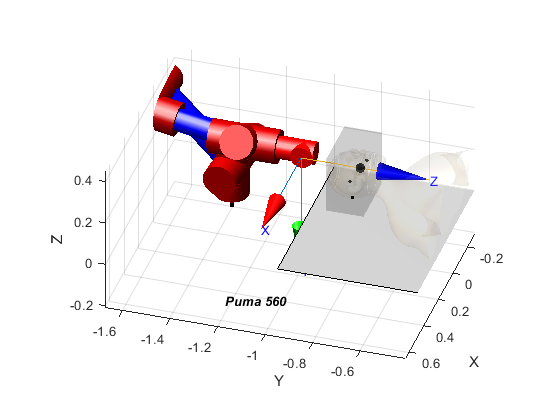

xlim([-0.296 0.651])
ylim([-1.67 -0.41])
zlim([-0.210 0.452])
view([107.069 33.606])

P = tumor_center_U(1:3);
P = transl(P) * trotx(-0.5*pi);

zeroTrajPoint = P * transl(0,0,-0.25);

initialTrajPoint = P * transl(0,0,-0.2);

% Se toma un offset de 0.05 metros debido a que no coincide exactamente la
% representación de la punta de la herramienta con el origen del sistema
% del End Effector 
finalTrajPoint = P * transl(0,0,-0.05);

B2_zero = ctraj(zeroTrajPoint,initialTrajPoint,30);
trajectoryB20 = p560.ikine6s(B2_zero,'run');


B2_go = ctraj(initialTrajPoint,finalTrajPoint,200);
trajectoryB21 = p560.ikine6s(B2_go,'run');

B2_return = ctraj(finalTrajPoint,initialTrajPoint,200);
trajectoryB22 = p560.ikine6s(B2_return,'run');

B2_final = ctraj(initialTrajPoint,zeroTrajPoint,30);
trajectoryB23 = p560.ikine6s(B2_final,'run');

trajectoryB2 = [trajectoryB20 ; trajectoryB21 ; trajectoryB22 ; trajectoryB23];

p560.plot(trajectoryB2)

%p560.plot(real(trajectoryB2),'movie','FA_BIOPSY_2.mp4')

#### Part 3 : Leaving the biopsy needle

xlim([-0.73 1.40])
ylim([-2.64 0.18])
zlim([-0.69 0.8])
view([69.73 36.93])

P = tumor_center_U(1:3);
P = transl(P) * trotx(-0.5*pi) * transl(0,0,-0.25)

P =     1.0000         0         0    0.0080
         0         0    1.0000   -1.0456
         0   -1.0000         0    0.2275
         0         0         0    1.0000



ini_point = P;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryB31 = p560.ikine6s(real(Q),'run');

tool1 = [0.8 -1.15 -0.62]

tool1 =     0.8000   -1.1500   -0.6200


tool1 = transl(tool1) * troty(pi/2) * transl(0,0,-0.25)

tool1 =          0         0    1.0000    0.5500
         0    1.0000         0   -1.1500
   -1.0000         0         0   -0.6200
         0         0         0    1.0000


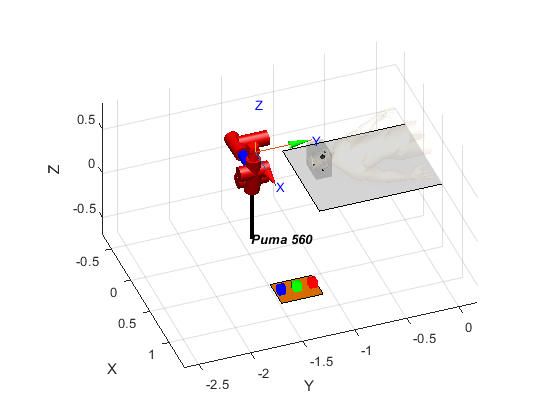

ini_point = transl(p560.fkine(qz).t);
end_point = tool1;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryB32 = p560.ikine6s(real(Q),'run');

ini_point = tool1;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryB33 = p560.ikine6s(real(Q),'run');

trajectoryB3 = [trajectoryB31 ; trajectoryB32 ; trajectoryB33];

p560.plot(real(trajectoryB3))

%p560.plot(real(trajectoryB3),'movie','FA_BIOPSY_3.mp4')

### Trepanation

#### Part 1 : Getting the trepanation drill

xlim([-0.73 1.40])
ylim([-2.64 0.18])
zlim([-0.69 0.8])
view([69.73 36.93])

p560.tool = transl(0,0,0.2)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (-0.2, -1.4, 0), RPY/xyz = (0, 0, 0) deg            
tool:    t = (0, 0, 0.2), RPY/xyz = (0, 0, 0) deg                
 



tool2 = [0.8 -1.3 -0.62]

tool2 =     0.8000   -1.3000   -0.6200


tool2 = transl(tool2) * troty(pi/2) * transl(0,0,-0.2)

tool2 =          0         0    1.0000    0.6000
         0    1.0000         0   -1.3000
   -1.0000         0         0   -0.6200
         0         0         0    1.0000



ini_point = transl(p560.fkine(qz).t);
end_point = tool2;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryT11 = p560.ikine6s(real(Q),'run');

ini_point = tool2;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryT12 = p560.ikine6s(real(Q),'run');

P = tumor_center_U(1:3);
P = transl(P) * trotx(-0.5*pi) * transl(0,0,-0.23)

P =     1.0000         0         0    0.0080
         0         0    1.0000   -1.0256
         0   -1.0000         0    0.2275
         0         0         0    1.0000


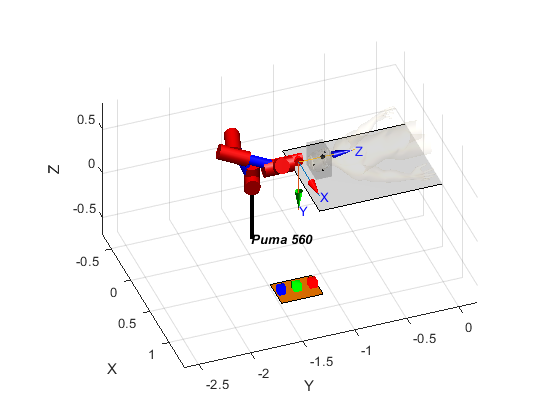


ini_point = transl(p560.fkine(qz).t);
end_point = P;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryT13 = p560.ikine6s(real(Q),'run');

trajectoryT1 = [trajectoryT11 ; trajectoryT12 ; trajectoryT13];

p560.plot(real(trajectoryT1))

%p560.plot(real(trajectoryT1),'movie','FA_TREPANATION_1.mp4')

#### Part 2 : Trepanating the skull

First we will plot our smaller but real-sized trepanation.

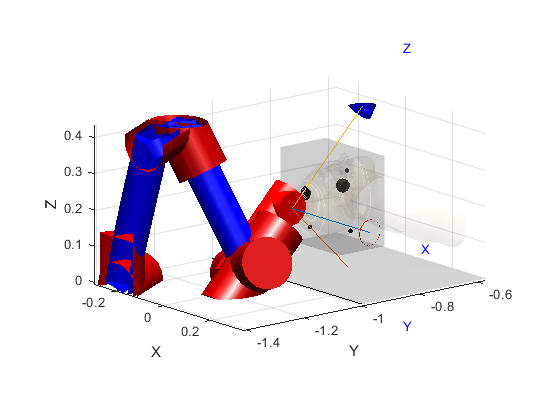

xlim([-0.293 0.338])
ylim([-1.408 -0.572])
zlim([-0.005 0.436])
view([50.718 14.590])

load('Cone.mat')
fvc.vertices = fvc.vertices * r;
vert = [fvc.vertices , ones([42,1])];
vert = (trans_skull * trotx(pi) * vert')';

meanCone = mean(vert(:,1:3));
vert = (transl(0,-0.12,0) * transl(tumor_center_U(1:3)) * transl(-meanCone) * vert')';

hold on

patch('Vertices',vert(:,1:3),'Faces',fvc.faces,'FaceVertexCData',hsv(6),'FaceColor','b','FaceAlpha',0.3)

P = tumor_center_U(1:3);
P = transl(P) * trotx(-0.5*pi) ;%* trotx(-pi/4);

aux_i = 1;

for i = 0:0.05:1
    P_CONE(:,:,aux_i) =  transl(tumor_center_U(1:3)) * trotx(-0.5*pi) * transl(0,0.0,-0.175) * trotz(2*pi*i) * transl(0,2*r,0) * trotx(pi/4);
    aux_i = aux_i + 1;
end

trajectory = p560.ikine6s(real(P_CONE));

p560.plot(real(trajectory))

%p560.plot(real(trajectory),'movie','FA_TREPANATION_2_SMALL.mp4')

And now we'll plot a version with a bigger trepanation cone to demonstrate our algorithm.

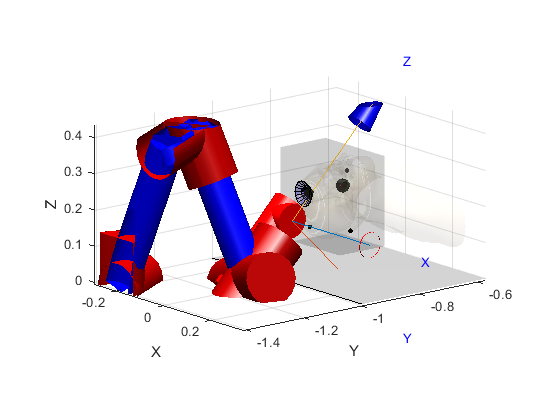

load('Cone.mat')
fvc.vertices = fvc.vertices * 2*r;
vert = [fvc.vertices , ones([42,1])];
vert = (trans_skull * trotx(pi) * vert')';

meanCone = mean(vert(:,1:3));
vert = (transl(0,-0.12,0) * transl(tumor_center_U(1:3)) * transl(-meanCone) * vert')';

hold on

patch('Vertices',vert(:,1:3),'Faces',fvc.faces,'FaceVertexCData',hsv(6),'FaceColor','b','FaceAlpha',0.3)

P = tumor_center_U(1:3);
P = transl(P) * trotx(-0.5*pi) ;%* trotx(-pi/4);

aux_i = 1;

for i = 0:0.05:1
    P_CONE(:,:,aux_i) =  transl(tumor_center_U(1:3)) * trotx(-0.5*pi) * transl(0,0.0,-0.175) * trotz(2*pi*i) * transl(0,2*2*r,0) * trotx(pi/4);
    aux_i = aux_i + 1;
end

trajectory = p560.ikine6s(real(P_CONE));

p560.plot(real(trajectory))

%p560.plot(real(trajectory),'movie','FA_TREPANATION_2_BIG.mp4')

#### Part 3 : Leaving the drill

xlim([-0.73 1.40])
ylim([-2.64 0.18])
zlim([-0.69 0.8])
view([69.73 36.93])

p560.tool = transl(0,0,0.2)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (-0.2, -1.4, 0), RPY/xyz = (0, 0, 0) deg            
tool:    t = (0, 0, 0.2), RPY/xyz = (0, 0, 0) deg                
 



P = tumor_center_U(1:3);
P = transl(P) * trotx(-0.5*pi) * transl(0,0,-0.23)

P =     1.0000         0         0    0.0080
         0         0    1.0000   -1.0256
         0   -1.0000         0    0.2275
         0         0         0    1.0000



ini_point = P;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryT31 = p560.ikine6s(real(Q),'run');

tool2 = [0.8 -1.3 -0.62]

tool2 =     0.8000   -1.3000   -0.6200


tool2 = transl(tool2) * troty(pi/2) * transl(0,0,-0.2)

tool2 =          0         0    1.0000    0.6000
         0    1.0000         0   -1.3000
   -1.0000         0         0   -0.6200
         0         0         0    1.0000


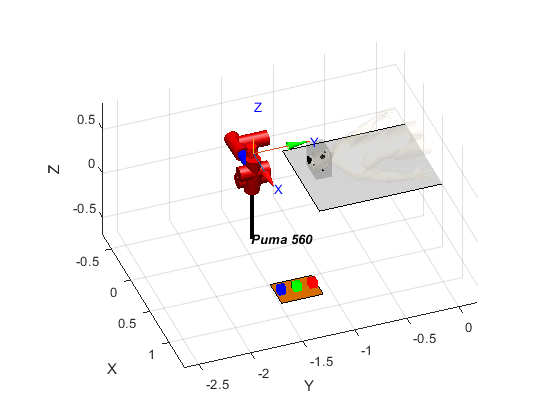


ini_point = transl(p560.fkine(qz).t);
end_point = tool2;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryT32 = p560.ikine6s(real(Q),'run');

ini_point = tool2;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryT33 = p560.ikine6s(real(Q),'run');


trajectoryT3 = [trajectoryT31 ; trajectoryT32 ; trajectoryT33];

p560.plot(real(trajectoryT3))

%p560.plot(real(trajectoryT3),'movie','FA_TREPANATION_3.mp4')

### Tumor burning

#### Part 1 : Getting the Laser

xlim([-0.73 1.40])
ylim([-2.64 0.18])
zlim([-0.69 0.8])
view([69.73 36.93])

tool3 = [0.8 -1.45 -0.62]

tool3 =     0.8000   -1.4500   -0.6200


tool3 = transl(tool3) * troty(pi/2) * transl(0,0,-0.2)

tool3 =          0         0    1.0000    0.6000
         0    1.0000         0   -1.4500
   -1.0000         0         0   -0.6200
         0         0         0    1.0000



ini_point = transl(p560.fkine(qz).t);
end_point = tool3;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryTb11 = p560.ikine6s(real(Q),'run');


ini_point = tool3;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryTb12 = p560.ikine6s(real(Q),'run');

P = tumor_center_U(1:3);
P = transl(P) * trotx(-0.5*pi) * transl(0,0,-0.2)

P =     1.0000         0         0    0.0080
         0         0    1.0000   -0.9956
         0   -1.0000         0    0.2275
         0         0         0    1.0000


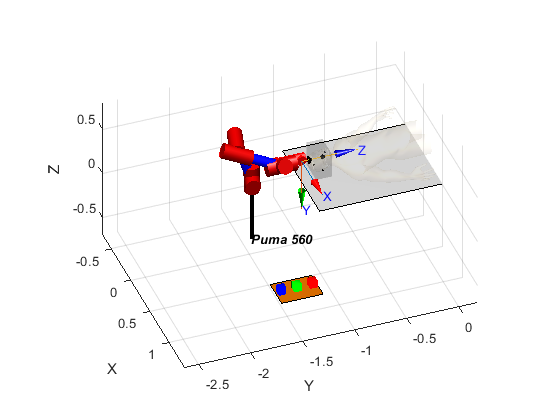


ini_point = transl(p560.fkine(qz).t);
end_point = P;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryTb13 = p560.ikine6s(real(Q),'run');

trajectoryTb1 = [trajectoryTb11 ; trajectoryTb12 ; trajectoryTb13];

p560.plot(real(trajectoryTb1))

%p560.plot(real(trajectoryTb1),'movie','FA_BURNING_1.mp4')

#### Part 2 : Creating and burning spheres of 4mm radius

In order to burn the tumor, we will divide it into spheres of 4mm radius. As the laser burns like a sphere of 4mm radius we just need to point the tool on each center of the spheres to burn the whole tumor.

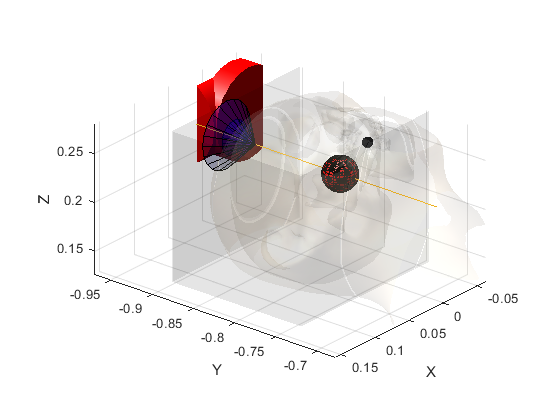

xlim([-0.063 0.158])
ylim([-0.970 -0.678])
zlim([0.126 0.281])
view([129.547 24.637])

spheres_center_tumor = plotting_spheres_tumor(r,tumor_center_U);

P = tumor_center_U(1:3);
P = transl(P) * trotx(-0.5*pi);

ini_point = P * transl(0,0,-0.2);
end_point = P * transl(0,0,-0.05);
Tb21a = ctraj(ini_point,end_point,100);
TrajectoryTb21(1:100,:) = p560.ikine6s(Tb21a,'run');

for i=1:(length(spheres_center_tumor)-1)
    ini_point2 = (transl(spheres_center_tumor(:,i))) * trotx(-0.5*pi) * transl(0,0,-0.05);
    end_point2 = (transl(spheres_center_tumor(:,i+1))) * trotx(-0.5*pi) * transl(0,0,-0.05);
    n = 5;
    Q = [];
    for j=1:n
        Q(:,:,j) = (1-j/n) * ini_point2 + (j/n) * (end_point2);
    end
    aux_trajectory = p560.ikine6s(real(Q),'run');
    TrajectoryTb22(1+(5*(i-1)):5*i,:) = aux_trajectory;
end

ini_point = (transl(spheres_center_tumor(:,length(spheres_center_tumor)))) * trotx(-0.5*pi) * transl(0,0,-0.05);
end_point = P * transl(0,0,-0.05);
n=20;
for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end
TrajectoryTb23 = p560.ikine6s(real(Q),'run');


ini_point = P * transl(0,0,-0.05);
end_point = P * transl(0,0,-0.2);
Tb21b = ctraj(ini_point,end_point,100);
TrajectoryTb24(1:100,:) = p560.ikine6s(Tb21b,'run');

TrajectoryTb2 = [TrajectoryTb21 ; TrajectoryTb22 ; TrajectoryTb23 ; TrajectoryTb24];

p560.plot(TrajectoryTb2)

%p560.plot(real(TrajectoryTb2),'movie','FA_BURNING_2.mp4')

#### Part 3 : Leaving the laser

xlim([-0.73 1.40])
ylim([-2.64 0.18])
zlim([-0.69 0.8])
view([69.73 36.93])

P = tumor_center_U(1:3);
P = transl(P) * trotx(-0.5*pi) * transl(0,0,-0.2)

P =     1.0000         0         0    0.0080
         0         0    1.0000   -0.9956
         0   -1.0000         0    0.2275
         0         0         0    1.0000



ini_point = P;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryTb31 = p560.ikine6s(real(Q),'run');

tool3 = [0.8 -1.45 -0.62]

tool3 =     0.8000   -1.4500   -0.6200


tool3 = transl(tool3) * troty(pi/2) * transl(0,0,-0.2)

tool3 =          0         0    1.0000    0.6000
         0    1.0000         0   -1.4500
   -1.0000         0         0   -0.6200
         0         0         0    1.0000



ini_point = transl(p560.fkine(qz).t);
end_point = tool3;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryTb32 = p560.ikine6s(real(Q),'run');


ini_point = tool3;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryTb33 = p560.ikine6s(real(Q),'run');


trajectoryTb3 = [trajectoryTb31 ; trajectoryTb32 ; trajectoryTb33];

p560.plot(real(trajectoryTb3))

%p560.plot(real(trajectoryTb3),'movie','FA_BURNING_3.mp4')

## *Second approach: ( 40%)*

We are now given a figure, which contains a setup consisting of a human laying on a table prepared to be operated. The fact that we are given this figure means we do not have any information about the reference frames at this environment, including the Universe/Laboratory reference frame, which was the essential one to our previous algorithms. 

We are asked to perform the same operation to the patient (*even if the position, poses and reference frames have changed it is important to notice ****we are performing the operation to the same person who has the very same tumor***).

In order to be able to do so we are given the three known fiducials points in this new Universal/Laboratory reference frame. Since we know  these fiducials position in both Box/Image and the (old) Universal reference frames, we pursue to discover the relationships between the Box (or Image) and old Universal RF with the new Universal RF.

We will refer to the new Universal reference frame as {NU}.

clf
figure(open('3_Second_approach_Patient_pose.fig'));

% Known information about the fiducials and old reference frames
M_U_B;

%We have been facing numerical errors, which are relatively small but
%affect our final outcome of the code, we believe these problems might come
%from having different fiducial points taken from the Dicom images
fiducial94_I = [0.12163 , 0.06231 , 94*1.4/1000 1]';

fiducial65_I = [0.18563 , 0.20934 , 65*1.4/1000 1]';

fiducial32_I = [0.07109 , 0.21394 , 32*1.4/1000 1]';

% Fiducials in NU
fiducial94_NU = [3.2779 2.8854 1.282 1]';
fiducial65_NU = [3.2782 2.9916 1.2914 1]';
fiducial32_NU = [3.3259 2.9595 1.4216 1]';

% Rotation part of the transformation matrix M_NU_F65

% Constructing the M_NU_F65 where FXX is the RF centered in the fiducial XX
% Notice we are generating one for each fiducial, where one would suffice,
% but in order to attach the numerical problems we talked about eariler, we
% will use a mean of the 3 generated matrices for the job.

AB1 = (fiducial32_NU(1:3) - fiducial65_NU(1:3))/ norm(fiducial32_NU(1:3) - fiducial65_NU(1:3))

AB1 =     0.3351
   -0.2255
    0.9148


CB1 = (fiducial94_NU(1:3) - fiducial65_NU(1:3))/norm(fiducial94_NU(1:3) - fiducial65_NU(1:3))

CB1 =    -0.0028
   -0.9961
   -0.0882


AB2 = (fiducial94_NU(1:3) - fiducial32_NU(1:3))/ norm(fiducial94_NU(1:3) - fiducial32_NU(1:3))

AB2 =    -0.2906
   -0.4486
   -0.8452


CB2 = (fiducial65_NU(1:3) - fiducial32_NU(1:3))/norm(fiducial65_NU(1:3) - fiducial32_NU(1:3))

CB2 =    -0.3351
    0.2255
   -0.9148


AB3 = (fiducial32_NU(1:3) - fiducial94_NU(1:3))/ norm(fiducial32_NU(1:3) - fiducial94_NU(1:3))

AB3 =     0.2906
    0.4486
    0.8452


CB3 = (fiducial65_NU(1:3) - fiducial94_NU(1:3))/norm(fiducial65_NU(1:3) - fiducial94_NU(1:3))

CB3 =     0.0028
    0.9961
    0.0882



Z_B1=cross(CB1, AB1)/norm(cross(CB1, AB1))

Z_B1 =    -0.9408
   -0.0273
    0.3379


Z_B2=cross(CB2, AB2)/norm(cross(CB2, AB2))

Z_B2 =    -0.9408
   -0.0273
    0.3379


Z_B3=cross(CB3, AB3)/norm(cross(CB3, AB3))

Z_B3 =     0.9408
    0.0273
   -0.3379



M_NU_F65 =oa2r(AB1, Z_B1) 

M_NU_F65 =    -0.0513    0.3351   -0.9408
   -0.9739   -0.2255   -0.0273
   -0.2213    0.9148    0.3379


M_NU_F32 =oa2r(AB2, Z_B2) 

M_NU_F32 =    -0.1746   -0.2906   -0.9408
    0.8933   -0.4486   -0.0273
   -0.4141   -0.8452    0.3379


M_NU_F94 =oa2r(AB3, Z_B3)

M_NU_F94 =    -0.1746    0.2906    0.9408
    0.8933    0.4486    0.0273
   -0.4141    0.8452   -0.3379



M_NU_F65 = [M_NU_F65 fiducial65_NU(1:3) ; 0 0 0 1]

M_NU_F65 =    -0.0513    0.3351   -0.9408    3.2782
   -0.9739   -0.2255   -0.0273    2.9916
   -0.2213    0.9148    0.3379    1.2914
         0         0         0    1.0000


M_NU_F32 = [M_NU_F32 fiducial32_NU(1:3) ; 0 0 0 1]

M_NU_F32 =    -0.1746   -0.2906   -0.9408    3.3259
    0.8933   -0.4486   -0.0273    2.9595
   -0.4141   -0.8452    0.3379    1.4216
         0         0         0    1.0000


M_NU_F94 = [M_NU_F94 fiducial94_NU(1:3) ; 0 0 0 1]

M_NU_F94 =    -0.1746    0.2906    0.9408    3.2779
    0.8933    0.4486    0.0273    2.8854
   -0.4141    0.8452   -0.3379    1.2820
         0         0         0    1.0000



% Notice this matrix is a proper tranformation matrix and it works
% perfectly when applied over the very same fiducial it was centered on.
inv(M_NU_F65) * fiducial65_NU

ans =     0.0000
         0
         0
    1.0000




%Constructing the M_B_FXX where F65 is the RF centered in the fiducial XX
AB1 = (fiducial32_I(1:3) - fiducial65_I(1:3))/ norm(fiducial32_I(1:3) - fiducial65_I(1:3))

AB1 =    -0.9268
    0.0372
   -0.3738


CB1 = (fiducial94_I(1:3) - fiducial65_I(1:3))/norm(fiducial94_I(1:3) - fiducial65_I(1:3))

CB1 =    -0.3869
   -0.8889
    0.2454


AB2 = (fiducial65_I(1:3) - fiducial32_I(1:3))/ norm(fiducial65_I(1:3) - fiducial32_I(1:3))

AB2 =     0.9268
   -0.0372
    0.3738


CB2 = (fiducial94_I(1:3) - fiducial32_I(1:3))/norm(fiducial94_I(1:3) - fiducial32_I(1:3))

CB2 =     0.2779
   -0.8337
    0.4772


AB3 = (fiducial32_I(1:3) - fiducial94_I(1:3))/ norm(fiducial32_I(1:3) - fiducial94_I(1:3))

AB3 =    -0.2779
    0.8337
   -0.4772


CB3 = (fiducial65_I(1:3) - fiducial94_I(1:3))/norm(fiducial65_I(1:3) - fiducial94_I(1:3))

CB3 =     0.3869
    0.8889
   -0.2454



Z_B1=cross(CB1, AB1)/norm(cross(CB1, AB1)) 

Z_B1 =     0.3323
   -0.3827
   -0.8620


Z_B2=cross(CB2, AB2)/norm(cross(CB2, AB2)) 

Z_B2 =    -0.3323
    0.3827
    0.8620


Z_B3=cross(CB3, AB3)/norm(cross(CB3, AB3)) 

Z_B3 =    -0.3323
    0.3827
    0.8620


M_B_F65 =oa2r(AB1, Z_B1) 

M_B_F65 =    -0.1751   -0.9268    0.3323
   -0.9231    0.0372   -0.3827
    0.3423   -0.3738   -0.8620


M_B_F32 =oa2r(AB2, Z_B2) 

M_B_F32 =    -0.1751    0.9268   -0.3323
   -0.9231   -0.0372    0.3827
    0.3423    0.3738    0.8620


M_B_F94 =oa2r(AB3, Z_B3)

M_B_F94 =     0.9013   -0.2779   -0.3323
    0.3981    0.8337    0.3827
    0.1707   -0.4772    0.8620



M_B_F65 = [M_B_F65 fiducial65_I(1:3) ; 0 0 0 1]

M_B_F65 =    -0.1751   -0.9268    0.3323    0.1856
   -0.9231    0.0372   -0.3827    0.2093
    0.3423   -0.3738   -0.8620    0.0910
         0         0         0    1.0000


M_B_F32 = [M_B_F32 fiducial32_I(1:3) ; 0 0 0 1]

M_B_F32 =    -0.1751    0.9268   -0.3323    0.0711
   -0.9231   -0.0372    0.3827    0.2139
    0.3423    0.3738    0.8620    0.0448
         0         0         0    1.0000


M_B_F94 = [M_B_F94 fiducial94_I(1:3) ; 0 0 0 1]

M_B_F94 = 4×4
    0.9013   -0.2779   -0.3323    0.1216
    0.3981    0.8337    0.3827    0.0623
    0.1707   -0.4772    0.8620    0.1316
         0         0         0    1.0000



% LINKING THE TWO AUXILIARY TRANSFORMATION MATRICES

M_NU_B1 = M_NU_F65 * inv(M_B_F65)

M_NU_B1 = 4×4
   -0.6143    0.4198    0.6681    3.2435
    0.3705    0.9010   -0.2255    2.7547
   -0.6967    0.1090   -0.7090    1.4624
         0         0         0    1.0000


M_NU_B2 = M_NU_F32 * inv(M_B_F32)

M_NU_B2 = 4×4
    0.0739   -0.1880   -0.9794    3.4047
   -0.5632   -0.8184    0.1146    3.1695
   -0.8230    0.5431   -0.1664    1.3714
         0         0         0    1.0000


M_NU_B3 = M_NU_F94 * inv(M_B_F94)

M_NU_B3 = 4×4
   -0.5508    0.5328    0.6425    3.2271
    0.6714    0.7401   -0.0381    2.7626
   -0.4958    0.4104   -0.7654    1.4175
         0         0         0    1.0000



% Notice the numerical errors we talked about, so we will generate the mean
% matrices instead.
M_NU_B1 * fiducial32_I

ans = 4×1
    3.3196
    2.9637
    1.4045
    1.0000


M_NU_B1 * fiducial65_I

ans = 4×1
    3.2782
    2.9916
    1.2914
    1.0000


M_NU_B1 * fiducial94_I

ans = 4×1
    3.2829
    2.8263
    1.2912
    1.0000



M_NU_B2 * fiducial32_I

ans = 4×1
    3.3259
    2.9595
    1.4216
    1.0000


M_NU_B2 * fiducial65_I

ans = 4×1
    3.2900
    2.9041
    1.3171
    1.0000


M_NU_B2 * fiducial94_I

ans = 4×1
    3.2731
    3.0651
    1.2832
    1.0000



M_NU_B3 * fiducial32_I

ans = 4×1
    3.3308
    2.9670
    1.4357
    1.0000


M_NU_B3 * fiducial65_I

ans = 4×1
    3.2949
    3.0387
    1.3417
    1.0000


M_NU_B3 * fiducial94_I

ans = 4×1
    3.2779
    2.8854
    1.2820
    1.0000



M_NU_B = (M_NU_B1 + M_NU_B2 + M_NU_B3) ./3

M_NU_B = 4×4
   -0.3637    0.2549    0.1104    3.2918
    0.1596    0.2742   -0.0497    2.8956
   -0.6718    0.3542   -0.5469    1.4171
         0         0         0    1.0000




%GETTING TO THE TRANSFORMATION BETWEEN UNIVERSAL MATRICES

M_U_NU1 = M_U_B * inv(M_NU_B1)

M_U_NU1 = 4×4
   -0.6143    0.3705   -0.6967    1.8656
    0.6681   -0.2255   -0.7090   -1.4123
   -0.4198   -0.9010   -0.1090    4.3283
         0         0         0    1.0000


M_U_NU2 = M_U_B * inv(M_NU_B2)

M_U_NU2 = 4×4
    0.0739   -0.5632   -0.8230    2.5369
   -0.9794    0.1146   -0.1664    2.2961
    0.1880    0.8184   -0.5431   -2.1641
         0         0         0    1.0000


M_U_NU3 = M_U_B * inv(M_NU_B3)

M_U_NU3 = 4×4
   -0.5508    0.6714   -0.4958    0.5004
    0.6425   -0.0381   -0.7654   -1.7867
   -0.5328   -0.7401   -0.4104    4.6706
         0         0         0    1.0000



M_U_NU = (M_U_NU1 + M_U_NU2 + M_U_NU3) ./3

M_U_NU = 4×4
   -0.3637    0.1596   -0.6718    1.6343
    0.1104   -0.0497   -0.5469   -0.3010
   -0.2549   -0.2742   -0.3542    2.2783
         0         0         0    1.0000


We are now going to repeat the same steps of the surgery seen before, a biopsy followed by a trepanation of the skull and finally the tumor ablation with the laser tool. We will plot an auxiliary tool table and proceed with the surgery.

We are avoiding the use of Matlab section breaks as there seems to be an issue with the given figure reseting at each section break.

%%%%%%%%%%%%%%%%%%%%%
%%% ROBOT CONFIG. %%%
%%%%%%%%%%%%%%%%%%%%%

mdl_puma560
p560.base = transl(3.5,3.4,0.75)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (3.5, 3.4, 0.75), RPY/xyz = (0, 0, 0) deg           
 


p560.tool = transl(0.05, 0, 0.25)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (3.5, 3.4, 0.75), RPY/xyz = (0, 0, 0) deg           
tool:    t = (0.05, 0, 0.25), RPY/xyz = (0, 0, 0) deg            
 


p560.plot(qz)
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% TOOL_TABLE && TOOLS %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%

view([60.89 37.18])
xlim([-1 4.5])
ylim([1.5 5.5])
zlim([-1.5 1.5])

hold on
Xt = [3.8 3.8 4.2 4.2];
Yt = [3.7 3.9 3.9 3.7];
Zt = [0.7 0.7 0.7 0.7];

% Scaling
tool_table = 1*[Xt; Yt; Zt];

% Homogeneous Coordinates
tool_table = [tool_table; ones(1,length(tool_table))];

trans_tool_table = transl(4,3.8,0.7);

hold on
patch(tool_table(1,:),tool_table(2,:),tool_table(3,:),[0.5 0.25 0])

%Tools
v= [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1];
v = [0.075* (v - 0.5*ones(8,3)) , ones(8,1) ];
f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];

%Tool 1
v1 = (trans_tool_table * v')';
v1 = (transl(0.15,0,0.075/2) * v1')';
v1 = v1(:,1:3);
FVsPlot(f,v1,[1,0,0],0,1)

%Tool 2
v2 = (trans_tool_table * v')';
v2 = (transl(0,0,0.075/2) * v2')';
v2 = v2(:,1:3);
FVsPlot(f,v2,[0,1,0],0,1)

%Tool 3
v3 = (trans_tool_table * v')';
v3 = (transl(-0.15,0,0.075/2) * v3')';
v3 = v3(:,1:3);
FVsPlot(f,v3,[0,0,1],0,1)

%%%%%%%%%%%%%
%%% TUMOR %%%
%%%%%%%%%%%%%

xmax_I = 0.148;
xmin_I = 0.118;
ymin_I = 0.080;
ymax_I = 0.115;
zmin_I = 65*1.4/1000;
zmax_I = 89*1.4/1000;

r = max([(xmax_I-xmin_I),(ymax_I-ymin_I),(zmax_I-zmin_I)]) / 2

r = 0.0175

[X,Y,Z] = sphere;

X2 = X * r;
Y2 = Y * r;
Z2 = Z * r;

tumor_center_I = [(xmax_I+xmin_I)/2, (ymax_I+ymin_I)/2, (zmax_I+zmin_I)/2, 1]';
tumor_center_U = M_NU_B * tumor_center_I;

hold on

surf(X2+tumor_center_U(1,1), Y2+tumor_center_U(2,1), Z2+tumor_center_U(3,1), 'FaceColor', [1,0,0])

### Biopsy

#### Part 1 : Getting the biopsy needle

tool1 = [3.85 3.8 0.8]

tool1 = 1×3
    3.8500    3.8000    0.8000


tool1 = transl(tool1) * trotx(-0.5*pi)

tool1 = 4×4
    1.0000         0         0    3.8500
         0         0    1.0000    3.8000
         0   -1.0000         0    0.8000
         0         0         0    1.0000



ini_point = transl(p560.fkine(qz).t);
end_point = tool1;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryB11 = p560.ikine6s(real(Q),'run');

ini_point = tool1;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryB12 = p560.ikine6s(real(Q),'run');

P = tumor_center_U(1:3);
P = transl(P) * transl(0,0,-0.25)

P = 4×4
    1.0000         0         0    3.2802
         0    1.0000         0    2.9382
         0         0    1.0000    1.0533
         0         0         0    1.0000



ini_point = transl(p560.fkine(qz).t);
end_point = P;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryB13 = p560.ikine6s(real(Q),'run');

trajectoryB1 = [trajectoryB11 ; trajectoryB12 ; trajectoryB13];

p560.plot(real(trajectoryB1))
%p560.plot(real(trajectoryB1),'movie','SA_BIOPSY_1.mp4')

#### Part 2 : Performing the biopsy

view([60.89 37.18])
xlim([2.924023834268927,3.535103177570944])
ylim([2.897255920357854,3.341677260941139])
zlim([1.042149318260936,1.3754653236984])

P = tumor_center_U(1:3);
P = transl(P);

zeroTrajPoint = P * transl(0,0,-0.25);

initialTrajPoint = P * transl(0,0,-0.2);

% Se toma un offset de 0.05 metros debido a que no coincide exactamente la
% representación de la punta de la herramienta con el origen del sistema
% del End Effector 
finalTrajPoint = P * transl(0,0,-0.05);

B2_zero = ctraj(zeroTrajPoint,initialTrajPoint,30);
trajectoryB20 = p560.ikine6s(B2_zero,'run');

B2_go = ctraj(initialTrajPoint,finalTrajPoint,200);
trajectoryB21 = p560.ikine6s(B2_go,'run');

B2_return = ctraj(finalTrajPoint,initialTrajPoint,200);
trajectoryB22 = p560.ikine6s(B2_return,'run');

B2_final = ctraj(initialTrajPoint,zeroTrajPoint,30);
trajectoryB23 = p560.ikine6s(B2_final,'run');

trajectoryB2 = [trajectoryB20 ; trajectoryB21 ; trajectoryB22 ; trajectoryB23];

p560.plot(trajectoryB2)
%p560.plot(real(trajectoryB2),'movie','SA_BIOPSY_2.mp4')

#### Part 3 : Leaving the biopsy needle

view([60.89 37.18])
xlim([-1 4.5])
ylim([1.5 5.5])
zlim([-1.5 1.5])


P = tumor_center_U(1:3);
P = transl(P) * transl(0,0,-0.25)

P = 4×4
    1.0000         0         0    3.2802
         0    1.0000         0    2.9382
         0         0    1.0000    1.0533
         0         0         0    1.0000



ini_point = P;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryB31 = p560.ikine6s(real(Q),'run');

tool1 = [3.85 3.8 0.8]

tool1 = 1×3
    3.8500    3.8000    0.8000


tool1 = transl(tool1) * trotx(-0.5*pi)

tool1 = 4×4
    1.0000         0         0    3.8500
         0         0    1.0000    3.8000
         0   -1.0000         0    0.8000
         0         0         0    1.0000


ini_point = transl(p560.fkine(qz).t);
end_point = tool1;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryB32 = p560.ikine6s(real(Q),'run');

ini_point = tool1;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryB33 = p560.ikine6s(real(Q),'run');

trajectoryB3 = [trajectoryB31 ; trajectoryB32 ; trajectoryB33];

p560.plot(real(trajectoryB3))
%p560.plot(real(trajectoryB3),'movie','SA_BIOPSY_3.mp4')

### Trepanation

#### Part 1 : Getting the trepanation drill

p560.tool = transl(0,0,0.2)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (3.5, 3.4, 0.75), RPY/xyz = (0, 0, 0) deg           
tool:    t = (0, 0, 0.2), RPY/xyz = (0, 0, 0) deg                
 



tool2 = [4 3.8 0.8]

tool2 = 1×3
    4.0000    3.8000    0.8000


tool2 = transl(tool2) * trotx(-0.5*pi)

tool2 = 4×4
    1.0000         0         0    4.0000
         0         0    1.0000    3.8000
         0   -1.0000         0    0.8000
         0         0         0    1.0000



ini_point = transl(p560.fkine(qz).t);
end_point = tool2;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryT11 = p560.ikine6s(real(Q),'run');

ini_point = tool2;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryT12 = p560.ikine6s(real(Q),'run');

P = tumor_center_U(1:3);
P = transl(P) * transl(0,0,-0.23)

P = 4×4
    1.0000         0         0    3.2802
         0    1.0000         0    2.9382
         0         0    1.0000    1.0733
         0         0         0    1.0000



ini_point = transl(p560.fkine(qz).t);
end_point = P;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryT13 = p560.ikine6s(real(Q),'run');

trajectoryT1 = [trajectoryT11 ; trajectoryT12 ; trajectoryT13];

p560.plot(real(trajectoryT1))
%p560.plot(real(trajectoryT1),'movie','SA_TREPANATION_1.mp4')

#### Part 2 : Trepanating the skull

First we will plot our smaller but real-sized trepanation.

view([60.89 37.18])
xlim([2.924023834268927,3.535103177570944])
ylim([2.897255920357854,3.341677260941139])
zlim([1.042149318260936,1.3754653236984])

load('Cone.mat')
fvc.vertices = fvc.vertices * r;
vert = [fvc.vertices , ones([42,1])];
%vert = (M_NU_B * trotx(pi) * vert')';

meanCone = mean(vert(:,1:3));
vert = (transl(0,0,-0.05) * transl(tumor_center_U(1:3)) * transl(-meanCone) * vert')';

hold on

patch('Vertices',vert(:,1:3),'Faces',fvc.faces,'FaceVertexCData',hsv(6),'FaceColor','b','FaceAlpha',0.3)

P = tumor_center_U(1:3);
P = transl(P);%* trotx(-pi/4);

aux_i = 1;

for i = 0:0.05:1
    P_CONE(:,:,aux_i) =  transl(tumor_center_U(1:3)) * transl(0,0.0,-0.085) * trotz(2*pi*i) * transl(0,2*r,0) * trotx(pi/4);
    aux_i = aux_i + 1;
end

trajectory = p560.ikine6s(real(P_CONE));

p560.plot(real(trajectory))
%p560.plot(real(trajectory),'movie','SA_TREPANATION_2.mp4')

#### Part 3 : Leaving the drill

view([60.89 37.18])
xlim([-1 4.5])
ylim([1.5 5.5])
zlim([-1.5 1.5])

P = tumor_center_U(1:3);
P = transl(P) * transl(0,0,-0.23)

P = 4×4
    1.0000         0         0    3.2802
         0    1.0000         0    2.9382
         0         0    1.0000    1.0733
         0         0         0    1.0000



ini_point = P;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryT31 = p560.ikine6s(real(Q),'run');

tool2 = [4 3.8 0.8]

tool2 = 1×3
    4.0000    3.8000    0.8000


tool2 = transl(tool2) * trotx(-0.5*pi)

tool2 = 4×4
    1.0000         0         0    4.0000
         0         0    1.0000    3.8000
         0   -1.0000         0    0.8000
         0         0         0    1.0000



ini_point = transl(p560.fkine(qz).t);
end_point = tool2;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryT32 = p560.ikine6s(real(Q),'run');

ini_point = tool2;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryT33 = p560.ikine6s(real(Q),'run');


trajectoryT3 = [trajectoryT31 ; trajectoryT32 ; trajectoryT33];

p560.plot(real(trajectoryT3))
%p560.plot(real(trajectoryT3),'movie','SA_TREPANATION_3.mp4')

### Tumor burning

#### Part 1 : Getting the Laser

tool3 = [4.15 3.8 0.8]

tool3 = 1×3
    4.1500    3.8000    0.8000


tool3 = transl(tool3) * trotx(-0.5*pi)

tool3 = 4×4
    1.0000         0         0    4.1500
         0         0    1.0000    3.8000
         0   -1.0000         0    0.8000
         0         0         0    1.0000



ini_point = transl(p560.fkine(qz).t);
end_point = tool3;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryTb11 = p560.ikine6s(real(Q),'run');


ini_point = tool3;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryTb12 = p560.ikine6s(real(Q),'run');

P = tumor_center_U(1:3);
P = transl(P) * transl(0,0,-0.2)

P = 4×4
    1.0000         0         0    3.2802
         0    1.0000         0    2.9382
         0         0    1.0000    1.1033
         0         0         0    1.0000



ini_point = transl(p560.fkine(qz).t);
end_point = P;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryTb13 = p560.ikine6s(real(Q),'run');

trajectoryTb1 = [trajectoryTb11 ; trajectoryTb12 ; trajectoryTb13];

p560.plot(real(trajectoryTb1))
%p560.plot(real(trajectoryTb1),'movie','SA_BURNING_1.mp4')

#### Part 2 : Creating and burning spheres of 4mm radius

view([60.89 37.18])
xlim([2.924023834268927,3.535103177570944])
ylim([2.897255920357854,3.341677260941139])
zlim([1.042149318260936,1.3754653236984])

spheres_center_tumor = plotting_spheres_tumor(r,tumor_center_U);

P = tumor_center_U(1:3);
P = transl(P);

ini_point = P * transl(0,0,-0.2);
end_point = P * transl(0,0,-0.05);
Tb21a = ctraj(ini_point,end_point,100);
TrajectoryTb21(1:100,:) = p560.ikine6s(Tb21a,'run');

for i=1:(length(spheres_center_tumor)-1)
    ini_point2 = (transl(spheres_center_tumor(:,i))) * transl(0,0,-0.05);
    end_point2 = (transl(spheres_center_tumor(:,i+1))) * transl(0,0,-0.05);
    n = 5;
    Q = [];
    for j=1:n
        Q(:,:,j) = (1-j/n) * ini_point2 + (j/n) * (end_point2);
    end
    aux_trajectory = p560.ikine6s(real(Q),'run');
    TrajectoryTb22(1+(5*(i-1)):5*i,:) = aux_trajectory;
end

ini_point = (transl(spheres_center_tumor(:,length(spheres_center_tumor)))) * transl(0,0,-0.05);
end_point = P * transl(0,0,-0.05);
n=20;
for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end
TrajectoryTb23 = p560.ikine6s(real(Q),'run');


ini_point = P * transl(0,0,-0.05);
end_point = P * transl(0,0,-0.2);
Tb21b = ctraj(ini_point,end_point,100);
TrajectoryTb24(1:100,:) = p560.ikine6s(Tb21b,'run');

TrajectoryTb2 = [TrajectoryTb21 ; TrajectoryTb22 ; TrajectoryTb23 ; TrajectoryTb24];

p560.plot(TrajectoryTb2)
%p560.plot(real(TrajectoryTb2),'movie','SA_BURNING_2.mp4')

#### Part 3 : Leaving the laser

view([60.89 37.18])
xlim([-1 4.5])
ylim([1.5 5.5])
zlim([-1.5 1.5])

P = tumor_center_U(1:3);
P = transl(P) * transl(0,0,-0.2)

P = 4×4
    1.0000         0         0    3.2802
         0    1.0000         0    2.9382
         0         0    1.0000    1.1033
         0         0         0    1.0000



ini_point = P;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryTb31 = p560.ikine6s(real(Q),'run');

tool3 = [4.15 3.8 0.8]

tool3 = 1×3
    4.1500    3.8000    0.8000


tool3 = transl(tool3) * trotx(-0.5*pi)

tool3 = 4×4
    1.0000         0         0    4.1500
         0         0    1.0000    3.8000
         0   -1.0000         0    0.8000
         0         0         0    1.0000


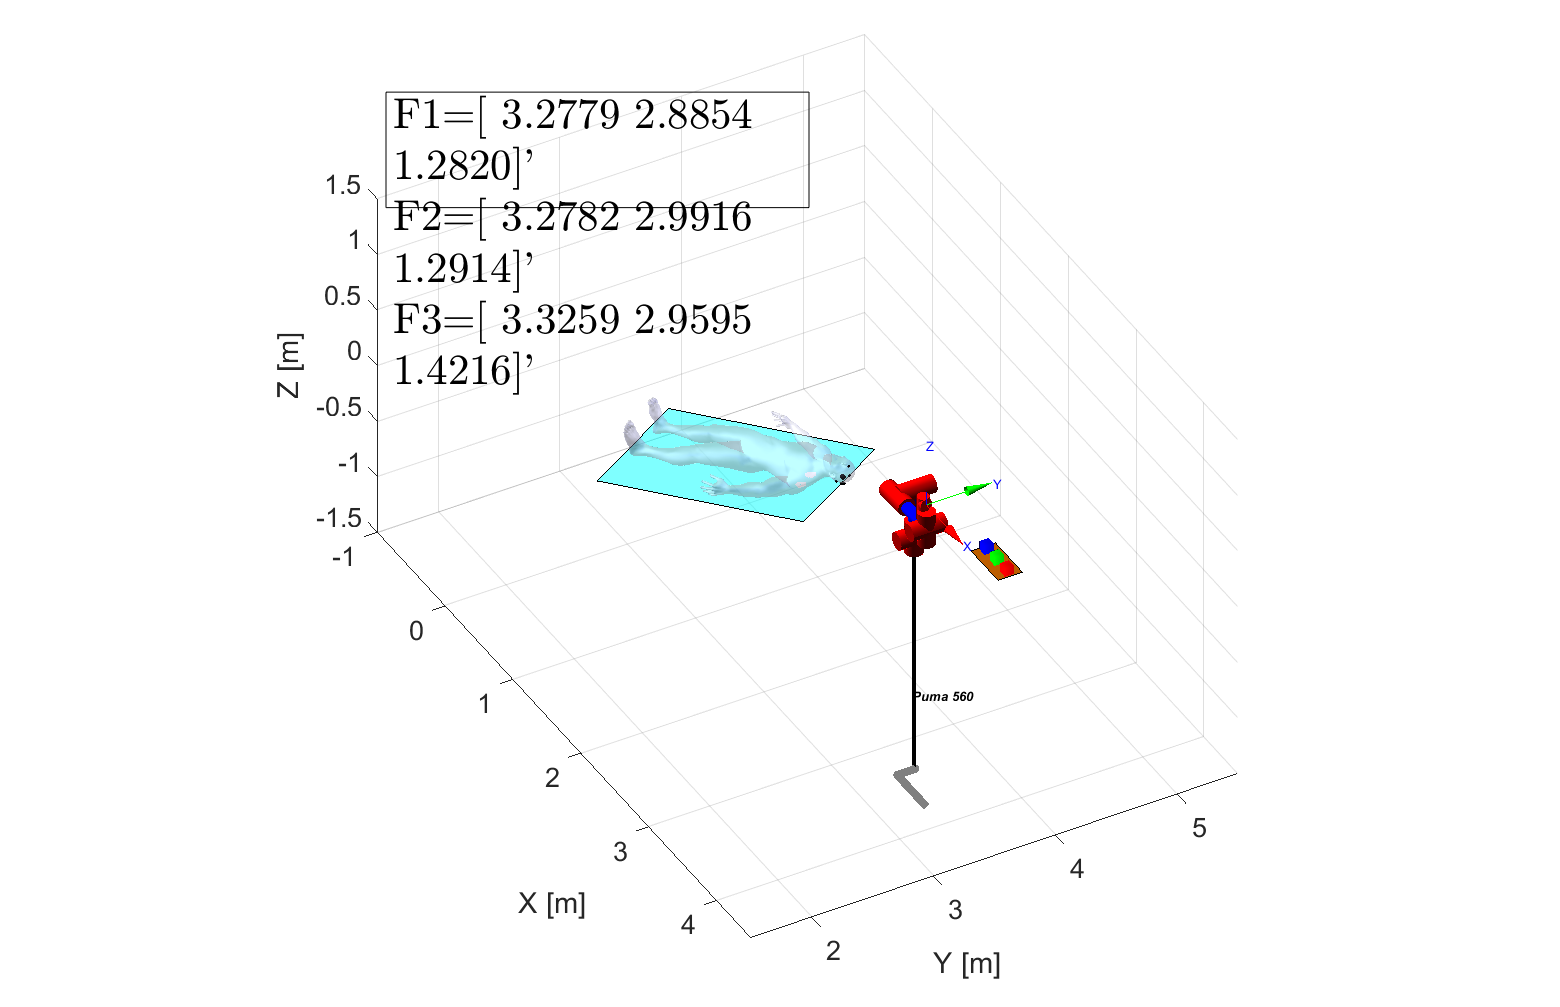


ini_point = transl(p560.fkine(qz).t);
end_point = tool3;
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryTb32 = p560.ikine6s(real(Q),'run');


ini_point = tool3;
end_point = transl(p560.fkine(qz).t);
n = 20;

for i=1:n
    Q(:,:,i) = (1-i/n) * ini_point + (i/n) * (end_point) ;
end

trajectoryTb33 = p560.ikine6s(real(Q),'run');


trajectoryTb3 = [trajectoryTb31 ; trajectoryTb32 ; trajectoryTb33];

p560.plot(real(trajectoryTb3))

%p560.plot(real(trajectoryTb3),'movie','SA_BURNING_3.mp4')

### Biopsy trajectory and velocity plot

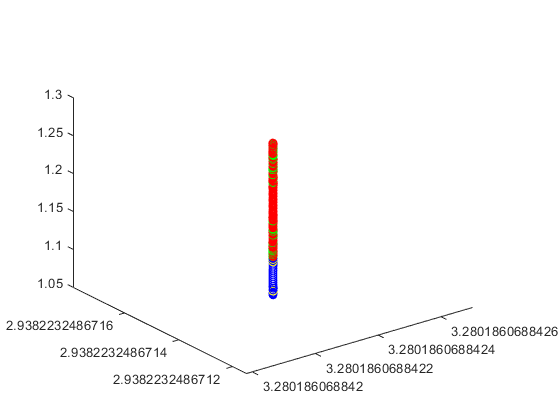

%%%%%%%%%%%%%%%%%%%%%%%%%
%% TRAJECTORY PLOTTING %%
%%%%%%%%%%%%%%%%%%%%%%%%%

figure

for i = 1:30
    plot3(B2_zero(1,4,i),B2_zero(2,4,i),B2_zero(3,4,i),'Marker','o','Color','y')
    hold on
end
view(3)

for i = 1:200
    plot3(B2_go(1,4,i),B2_go(2,4,i),B2_go(3,4,i),'Marker','o','Color','g')
    hold on
end

for i = 1:200
    plot3(B2_return(1,4,i),B2_return(2,4,i),B2_return(3,4,i),'Marker','o','Color','r')
    hold on
end

for i = 1:30
    plot3(B2_final(1,4,i),B2_final(2,4,i),B2_final(3,4,i),'Marker','o','Color','b')
    hold on
end

 We are plotting the velocity in the {EE} Z-Axis since it is the one where the action takes place. Notice in the resulting plot the significant spikes:

- During the first 30 frames the manipulator approaches the head at a not-so-slow pace, around mid-way of the trip it stops accelerating and starts to slow down to arrive at the head surface at velocity 0.

- Now the drilling through the head starts, and one should notice how this process is done at a way slower pace. Again, it can be seen that the process arrives at the center of the tumor around frame 230, where the velocity is 0.

- At frame 230 the tissue sample is taken at velocity 0 and it starts marching its way back to the entrance point at a very slow pace.

- Once it has arrived to the head surface it can go back to the initial position at a faster rate than when moving inside the head (seen around frame 430).

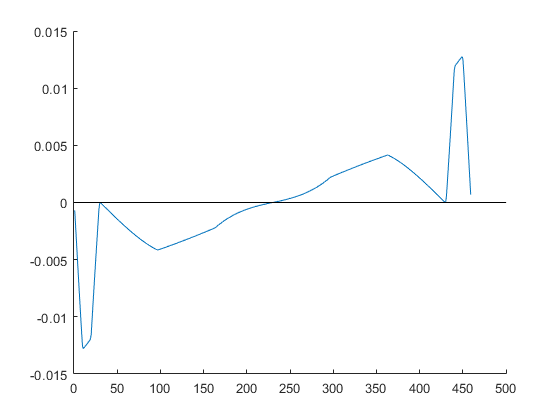

%%%%%%%%%%%%%%%%%%%%%%%%%
%%   z-AXIS VELOCITY   %%
%%%%%%%%%%%%%%%%%%%%%%%%%

% Notice how we calculate the derivative of theta by hand, calculating the
% offset of the angles generated between one frame and its successor

for i = 1:(length(trajectoryB2)-1)
    JE = p560.jacobe(trajectoryB2(i,:));
    iJE = inv(JE);
    dif = trajectoryB2(i+1,:) - trajectoryB2(i,:);
    vel(i,:) = (iJE * dif')';
end

figure

z = 1:(length(trajectoryB2-1)-1);

y = vel(:,3);

line(z,y)

hold on

line([0,500],[0,0],'color','k')

xlim([-1 501])
ylim([-0.015 0.015])

### Trepanation.

 Plot the manipulability index during all time trepanation is been performed. Plot the velocities ellipsoide when the manipulability is lower.

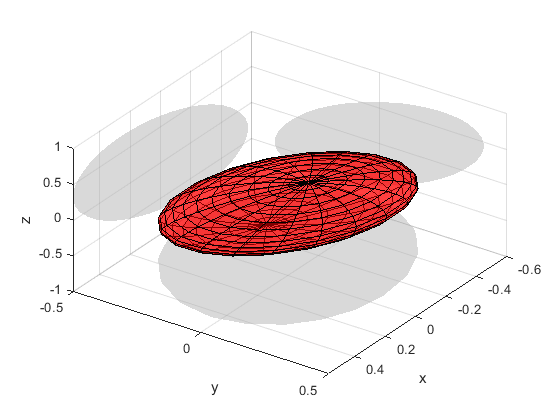

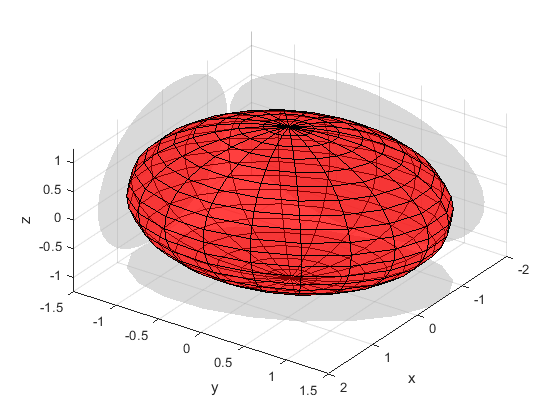

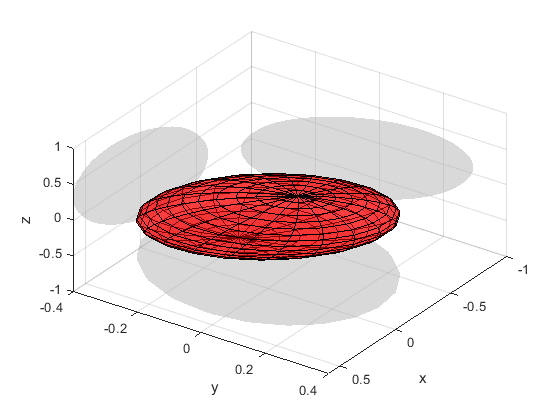

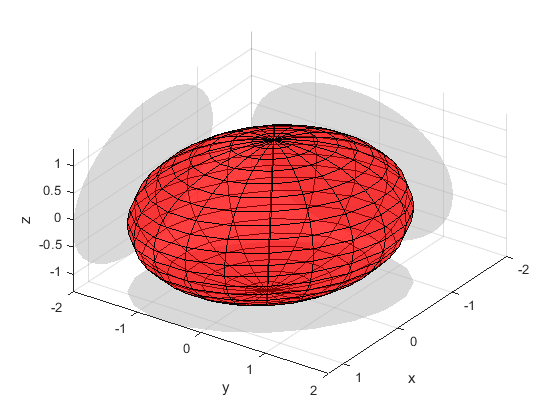

trajectoryT2 = trajectory;

for i=1:length(trajectoryT2)
  m(i,1) = p560.maniplty(trajectoryT2(i,:)) ;
  if m(i,1) < 0.05
      %Translational ellipse
      J = p560.jacob0(trajectoryT2(i,:));
      JT = J(1:3,:);
      figure
      plot_ellipse(JT*JT','fillcolor','r','alpha',0.5,'shadow')
      view (125,45)
      xyzlabel
      grid on
      
      %Rotational ellipse
      JR = J(4:6,:);
      figure
      plot_ellipse(JR*JR','fillcolor','r','alpha',0.5,'shadow')
      view (125,45)
      xyzlabel
      grid on
  end
end


% We have chosen to display the two lowest manipulability indexes 
% (those lower than 0.05)
m

m =     0.0548
    0.0650
    0.0737
    0.0786
    0.0786
    0.0749
    0.0701
    0.0669
    0.0674
    0.0717


### How long it takes the ablation of all the tumor.

The ablation time is measured using the video generated form the surgery procedure. Please refer to said video 'SA_BURNING_2.mp4' , **which has a duration of 5 minutes and 47 seconds (347 seconds).**

### FUNCIONES AUXILIARES

function FVsPlot(F,V,color,addLight,fa)
patch('Faces',F,'Vertices',V,'FaceColor',color, ...
         'FaceAlpha',fa,...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
if addLight == 1
    camlight('headlight');
end

material('dull');

grid on
xlabel 'X [m]'
ylabel 'Y [m]'
zlabel 'Z [m]'
end

function spheres_center = plotting_spheres_tumor(r,tumor_center_U)
r2 = 0.004;
[X,Y,Z] = sphere;

X3 = X * r2;
Y3 = Y * r2;
Z3 = Z * r2;

hold on
cont = 1;

aux = tumor_center_U;
for i = 0:1.5*ceil(r/r2) 
    for j = 0:1.5*ceil(r/r2)
        for k = 0:1.5*ceil(r/r2)
            p1 = [tumor_center_U(1,1) + i*r2/1.5; tumor_center_U(2,1) + j*r2/1.5; tumor_center_U(3,1) + k*r2/1.5];
            p2 = [tumor_center_U(1,1) + i*r2/1.5; tumor_center_U(2,1) - j*r2/1.5; tumor_center_U(3,1) + k*r2/1.5];
            p3 = [tumor_center_U(1,1) + i*r2/1.5; tumor_center_U(2,1) + j*r2/1.5; tumor_center_U(3,1) - k*r2/1.5];
            p4 = [tumor_center_U(1,1) + i*r2/1.5; tumor_center_U(2,1) - j*r2/1.5; tumor_center_U(3,1) - k*r2/1.5];
            p5 = [tumor_center_U(1,1) - i*r2/1.5; tumor_center_U(2,1) - j*r2/1.5; tumor_center_U(3,1) - k*r2/1.5];
            p6 = [tumor_center_U(1,1) - i*r2/1.5; tumor_center_U(2,1) + j*r2/1.5; tumor_center_U(3,1) - k*r2/1.5];
            p7 = [tumor_center_U(1,1) - i*r2/1.5; tumor_center_U(2,1) - j*r2/1.5; tumor_center_U(3,1) + k*r2/1.5];
            p8 = [tumor_center_U(1,1) - i*r2/1.5; tumor_center_U(2,1) + j*r2/1.5; tumor_center_U(3,1) + k*r2/1.5];
            
            if norm(abs(p1 - tumor_center_U(1:3))) <= r - r2
                spheres_center(:,cont) = p1;
                cont = cont + 1;
                surf(X3+p1(1,1),Y3+p1(2,1),Z3+p1(3,1), 'FaceColor',[0,1,0])
       
                spheres_center(:,cont) = p2;
                cont = cont + 1;
                surf(X3+p2(1,1),Y3+p2(2,1),Z3+p2(3,1), 'FaceColor',[0,1,0])
                
                spheres_center(:,cont) = p3;
                cont = cont + 1;
                surf(X3+p3(1,1),Y3+p3(2,1),Z3+p3(3,1), 'FaceColor',[0,1,0])
                
                spheres_center(:,cont) = p4;
                cont = cont + 1;
                surf(X3+p4(1,1),Y3+p4(2,1),Z3+p4(3,1), 'FaceColor',[0,1,0])
                
                spheres_center(:,cont) = p5;
                cont = cont + 1;
                surf(X3+p5(1,1),Y3+p5(2,1),Z3+p5(3,1), 'FaceColor',[0,1,0])
                
                spheres_center(:,cont) = p6;
                cont = cont + 1;
                surf(X3+p6(1,1),Y3+p6(2,1),Z3+p6(3,1), 'FaceColor',[0,1,0])
                
                spheres_center(:,cont) = p7;
                cont = cont + 1;
                surf(X3+p7(1,1),Y3+p7(2,1),Z3+p7(3,1), 'FaceColor',[0,1,0])
                
                spheres_center(:,cont) = p8;
                cont = cont + 1;
                surf(X3+p8(1,1),Y3+p8(2,1),Z3+p8(3,1), 'FaceColor',[0,1,0])
            end
        end
    end
end
end